**2026-01-30  **

**SINGLE DIRECTION FUNCTIONAL GRADING - LINEAR STIFFNESS GRADING - SKELETAL-BASED STRUCTURE**

**REFERENCE TO AbouAli2019-Mechanical Response of 3D Bending-Dominated Ligament-Based**

**AbouAli2019 - Gyroid - Polymeric material - Cell size 8 mm**

**test to determine the a and b coefficients of the isovalue-relative density relation  **

**\rho_r = a*c + b**

**v1 = +c -- c = 1.3**

clc;
clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 1.3; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 8; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: 1.3000
           v2: 0
    voxelSize: 0.1500
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

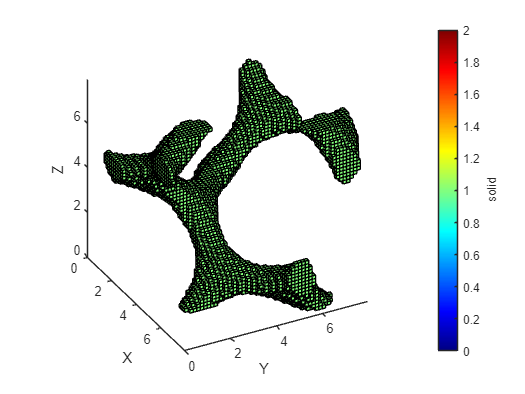

axesVoxel = myCell.plot("voxel","solid");

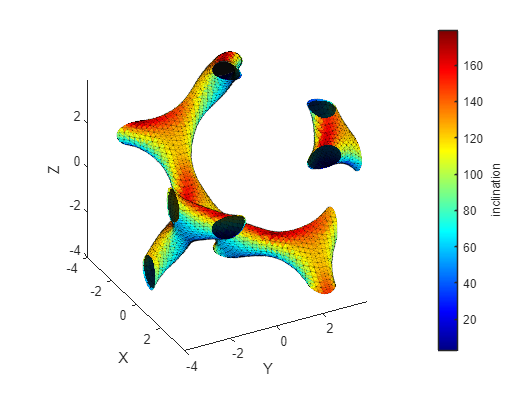

axesVoxel = myCell.plot("SurfMesh","inclination");

% X = ['for c = 0.1, relative volume = ' num2str(myCell.M.relativeVolume*100) '%']
% disp(X)
isoval_rheldens_array = [V1; myCell.M.relativeVolume*100];

**v1 = +c -- c = 1.16**

% clc;
% clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 1.16; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 8; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: 1.1600
           v2: 0
    voxelSize: 0.1500
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

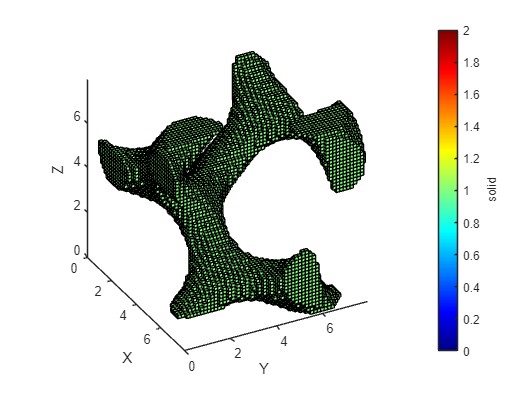

axesVoxel = myCell.plot("voxel","solid");

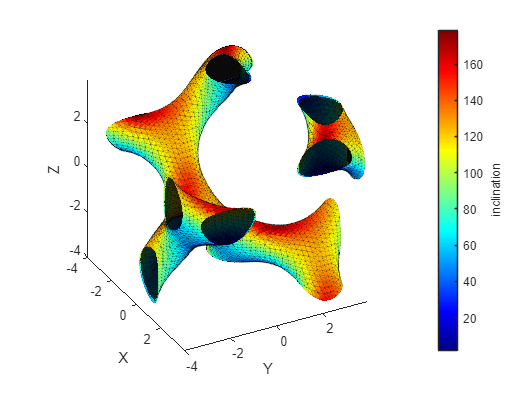

axesVoxel = myCell.plot("SurfMesh","inclination");

newdata = [V1; myCell.M.relativeVolume*100]

newdata =     1.1600
   11.4108


isoval_rheldens_array = [isoval_rheldens_array newdata];

**v1 = +c -- c = 1.04**

% clc;
% clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 1.04; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 8; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: 1.0400
           v2: 0
    voxelSize: 0.1500
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

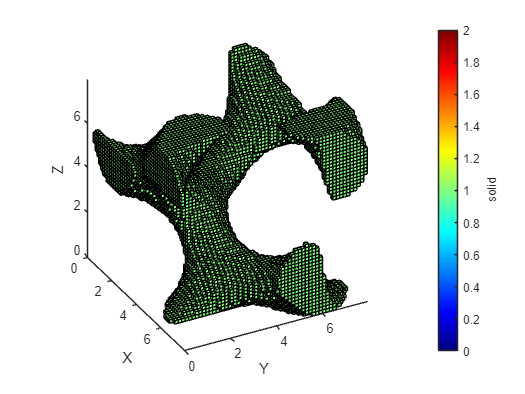

axesVoxel = myCell.plot("voxel","solid");

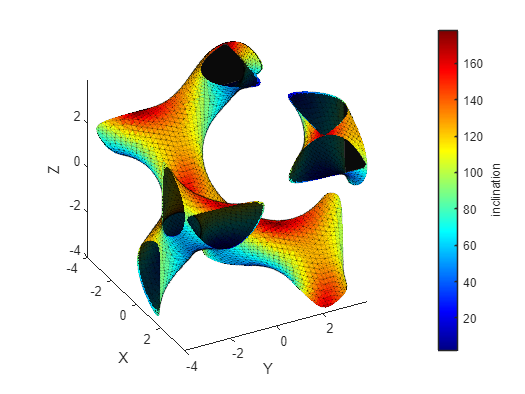

axesVoxel = myCell.plot("SurfMesh","inclination");

newdata = [V1; myCell.M.relativeVolume*100]

newdata =     1.0400
   15.6404


isoval_rheldens_array = [isoval_rheldens_array newdata];

**v1 = +c -- c = 0.92**

% clc;
% clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.92; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 8; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: 0.9200
           v2: 0
    voxelSize: 0.1500
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

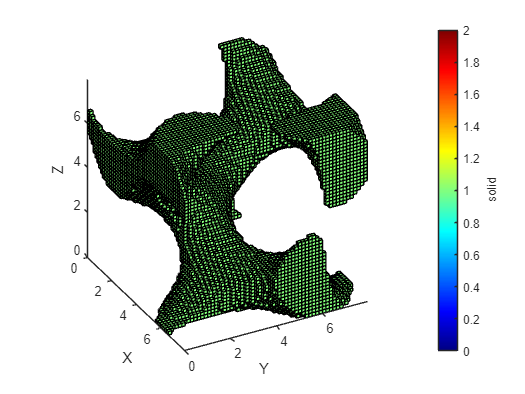

axesVoxel = myCell.plot("voxel","solid");

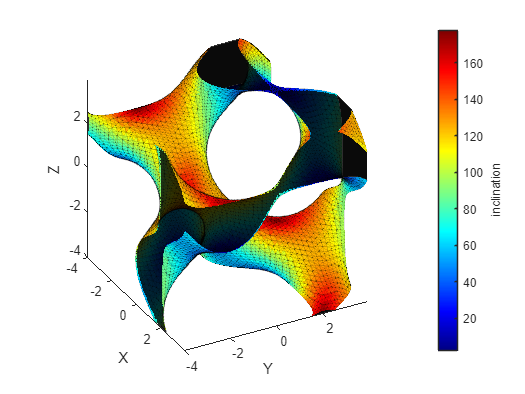

axesVoxel = myCell.plot("SurfMesh","inclination");

newdata = [V1; myCell.M.relativeVolume*100]

newdata =     0.9200
   19.7781


isoval_rheldens_array = [isoval_rheldens_array newdata];

**v1 = +c -- c = 0.8**

% clc;
% clear all;

% TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.8; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 8; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID

myEQUATION = func2str(EQ0);


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)
           v1: 0.8000
           v2: 0
    voxelSize: 0.1500
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]



calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

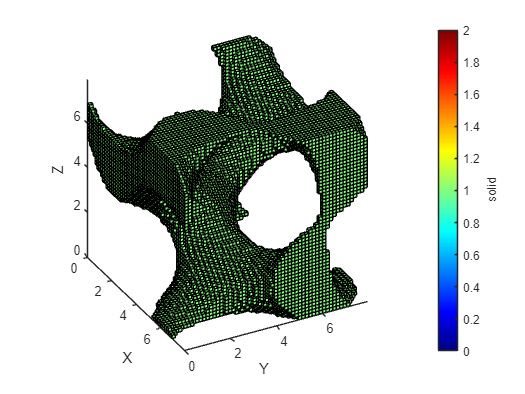

axesVoxel = myCell.plot("voxel","solid");

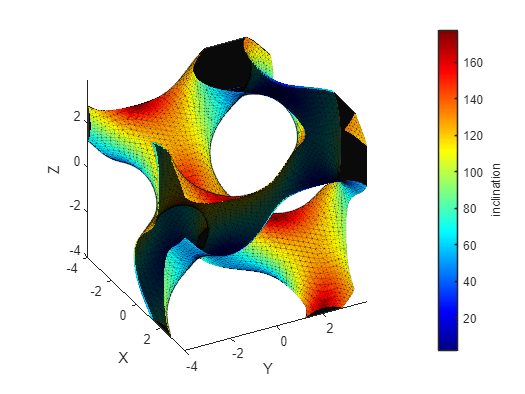

axesVoxel = myCell.plot("SurfMesh","inclination");

newdata = [V1; myCell.M.relativeVolume*100]

newdata =     0.8000
   23.7975


isoval_rheldens_array = [isoval_rheldens_array newdata];

**RESULTS OF 2026-01-30 **

** isoval_rheldens_array = **

**1.30000000000000	        1.16000000000000	        1.04000000000000        	0.920000000000000	0.800000000000000**

**6.21855625785044    	11.4107619041222    	15.6404280043257    	19.7780718311089    	23.7974972628411**

**the linear relationship between the isovalue c and the relative density \rho_r is confirmed**

**2026-01-30 **

**SINGLE DIRECTION FUNCTIONAL GRADING - LINEAR STIFFNESS GRADING - SKELETAL-BASED STRUCTURE**

**LINEAR FIT to determine the a and b coefficients of the isovalue-relative density relation  **

**\rho_r = a*c + b**

**RESULTS **

**a = 65.19 b=-0.27,**

** \rho_r [%] = -35.15*c +52.06**

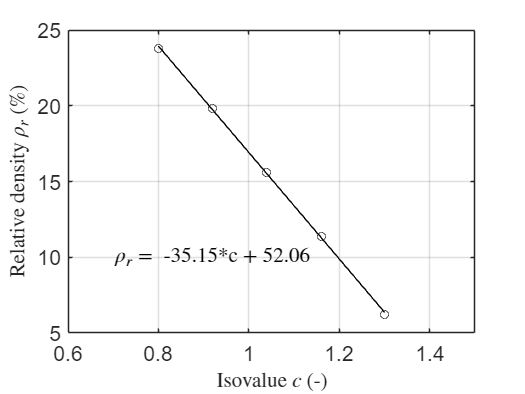

isovalues = [0.8, 0.92, 1.04, 1.16, 1.3];
rhel_dens = [23.8, 19.8, 15.6, 11.4, 6.22]; % [%]
linear_fit = polyfit(isovalues,rhel_dens,1);
rhel_dens_fit = linear_fit(1)*isovalues + linear_fit(2);

figure
plot(isovalues,rhel_dens,'o k','LineWidth',0.5) 
hold on;
plot(isovalues,rhel_dens_fit,'-k','LineWidth',0.5);

ax = gca; ax.FontSize = 16; 
xlabel('Isovalue $c$ (-)','interpreter','latex','fontsize',16);
ylabel('Relative density $\rho_r$ (\%)','interpreter','latex','fontsize',16);
xlim([0.6 1.5])
% ylim([0 7])

% lgd = legend([P1 P2 P3 P4 H2O],{'$\bar{\eta}$','$\bar{\eta}_W$','$\bar{\eta}_T$','$\bar{\eta}_L$','bulk water'},'interpreter','latex','Location','northeast');
% lgd.FontSize = 12;

hold off
grid on
box on
string = append('$\rho_r =$ ', sprintf("%.2f", linear_fit(1)), '*c + ', sprintf("%.2f", linear_fit(2)));
text(0.7,10,string,'fontsize',16,'interpreter','latex')

% annotation('textbox', [0.2, 0.8, 0.1, 0.4], 'String', "aaapi value is " + pi)

**2026-02-03  **

**PLOT REFERENCE CASE - AbouAli2019 - Gyroid - Polymeric material - Cell size 8 mm**

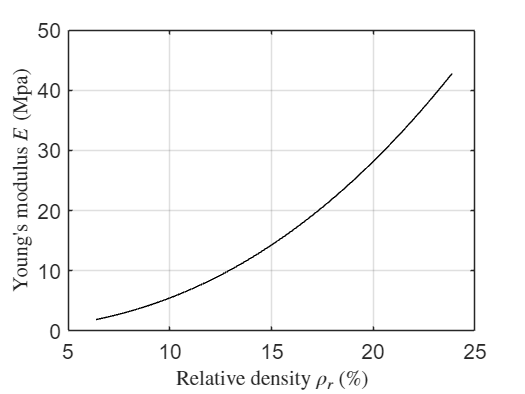

K_YoungMod_AbouAli2019 = 1257; % (MPa) 
N_YoungMod_AbouAli2019 = 2.36; % (-) 
RangeRD_AbouAli2019 = [6.37:0.05:23.9]/100;

YoungMod_fit_AbouAli2019 = (RangeRD_AbouAli2019.^N_YoungMod_AbouAli2019)*K_YoungMod_AbouAli2019; % (MPa)

figure
plot(RangeRD_AbouAli2019*100,YoungMod_fit_AbouAli2019,'-k','LineWidth',0.5);

ax = gca; ax.FontSize = 16; 

xlabel('Relative density $\rho_r$ (\%)','interpreter','latex','fontsize',16);
ylabel('Young''s modulus $E$ (Mpa)','interpreter','latex','fontsize',16);
xlim([5 25])
% ylim([0 7])

grid on
box on

**2026-02-03**

**STIFFNESS LINEAR GRADING OPTIMIZATION - TARGET DESIGN - 3x1x1 unit cells**

N_xcells = 3; % number of cells along x-direction 

x_A = -4*N_xcells; % (mm)
x_B = 4*N_xcells; % (mm)
y_A = 1.89; % (MPa)
y_B = 42.8; % (MPa)

alpha = (y_B - y_A)/(x_B - x_A); % result 1.7046
beta = (y_A*x_B - y_B*x_A)/(x_B - x_A); % result 22.345

**STIFFNESS LINEAR GRADING OPTIMIZATION - OPTIMAL ISOVALUE c(x)**

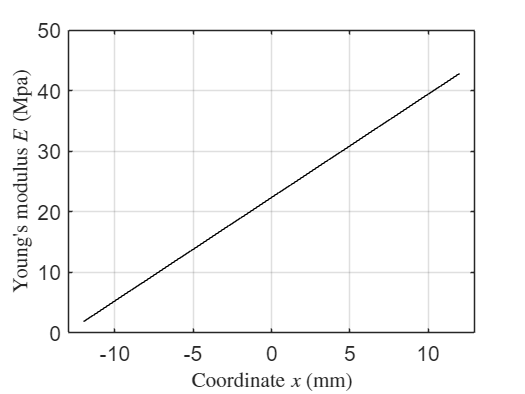

isovalue_opt_a1 = 1/(linear_fit(1)/100); % result -2.8451
isovalue_opt_a2 = -(linear_fit(2)/100)/(linear_fit(1)/100); % result 1.4811

%test
isovalue_opt_funct = @(x) -2.8451*((1.7046*x+22.345)/1257).^(1/2.36)+1.4811; %test

x_array_test = [x_A:0.1:x_B];
isovalue_opt_array_test = isovalue_opt_funct(x_array_test);
reldens_opt_array_test = linear_fit(1)/100*isovalue_opt_array_test + linear_fit(2)/100;
YoungMod_opt_array_test = K_YoungMod_AbouAli2019*reldens_opt_array_test.^N_YoungMod_AbouAli2019;

%%%%%%%%%%%%%%%% CHECK START
figure
plot(x_array_test(:), YoungMod_opt_array_test,'-k','LineWidth',0.5);

ax = gca; ax.FontSize = 16; 

xlabel('Coordinate $x$ (mm)','interpreter','latex','fontsize',16);
ylabel('Young''s modulus $E$ (Mpa)','interpreter','latex','fontsize',16);
xlim([-13 13])
% ylim([0 7])

grid on
box on

%%%%%%%%%%%%%%%% CHECK END

isovalue_opt = '-2.8451*((1.7046*x+22.345)/1257).^(1/2.36)+1.4811';

**STIFFNESS LINEAR GRADING OPTIMIZATION - SINGLE DIRECTION**

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID
myEQUATION = [func2str(EQ0) isovalue_opt];

% test = str2func(myEQUATION);

TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.0; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 8; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [N_xcells 1 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-2.8451*((1.7046*x+22.345)/1257).^(1/2.36)+1.4811'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-2.8451*((1.7046*x+22.345)/1257).^(1/2.36)+1.4811
           v1: 0
           v2: 0
    voxelSize: 0.1500
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]


calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

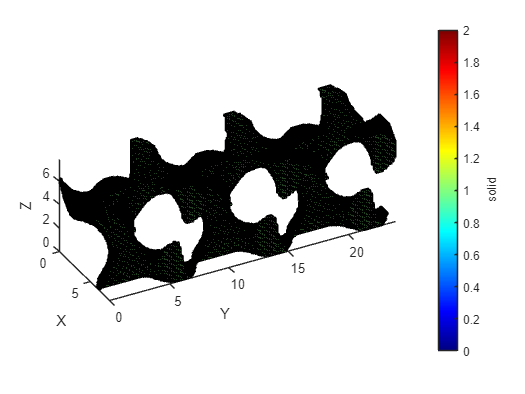

axesVoxel = myCell.plot("voxel","solid");

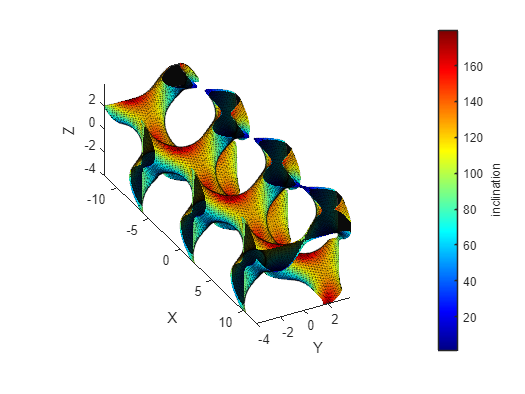

axesVoxel = myCell.plot("SurfMesh","inclination");

**TEST SECTION - 1**

**Y-DIRECTION**

**PLOT REFERENCE CASE - AbouAli2019 - Gyroid - Polymeric material - Cell size 8 mm**


N_xcells = 3; % number of cells along x-direction 

x_A = -4*N_xcells; % (mm)
x_B = 4*N_xcells; % (mm)
y_A = 1.89; % (MPa)
y_B = 42.8; % (MPa)

alpha = (y_B - y_A)/(x_B - x_A); % result 1.7046
beta = (y_A*x_B - y_B*x_A)/(x_B - x_A); % result 22.345

**STIFFNESS LINEAR GRADING OPTIMIZATION - OPTIMAL ISOVALUE c(x)**

isovalue_opt_a1 = 1/(linear_fit(1)/100); % result -2.8451
isovalue_opt_a2 = -(linear_fit(2)/100)/(linear_fit(1)/100); % result 1.4811

%test
isovalue_opt_funct = @(y) -2.8451*((1.7046*y+22.345)/1257).^(1/2.36)+1.4811; %test

x_array_test = [x_A:0.1:x_B];
isovalue_opt_array_test = isovalue_opt_funct(x_array_test);
reldens_opt_array_test = linear_fit(1)/100*isovalue_opt_array_test + linear_fit(2)/100;
YoungMod_opt_array_test = K_YoungMod_AbouAli2019*reldens_opt_array_test.^N_YoungMod_AbouAli2019;

%%%%%%%%%%%%%%%% CHECK START
figure
plot(x_array_test(:), YoungMod_opt_array_test,'-k','LineWidth',0.5);

ax = gca; ax.FontSize = 16; 

xlabel('Coordinate $x$ (mm)','interpreter','latex','fontsize',16);
ylabel('Young''s modulus $E$ (Mpa)','interpreter','latex','fontsize',16);
xlim([-13 13])
% ylim([0 7])

grid on
box on

%%%%%%%%%%%%%%%% CHECK END

isovalue_opt = '-2.8451*((1.7046*y+22.345)/1257).^(1/2.36)+1.4811';

**STIFFNESS LINEAR GRADING OPTIMIZATION - SINGLE DIRECTION**

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID
myEQUATION = [func2str(EQ0) isovalue_opt];

% test = str2func(myEQUATION);

TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.0; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 8; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 3 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-2.8451*((1.7046*y+22.345)/1257).^(1/2.36)+1.4811'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-2.8451*((1.7046*y+22.345)/1257).^(1/2.36)+1.4811
           v1: 0
           v2: 0
    voxelSize: 0.1500
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]


calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

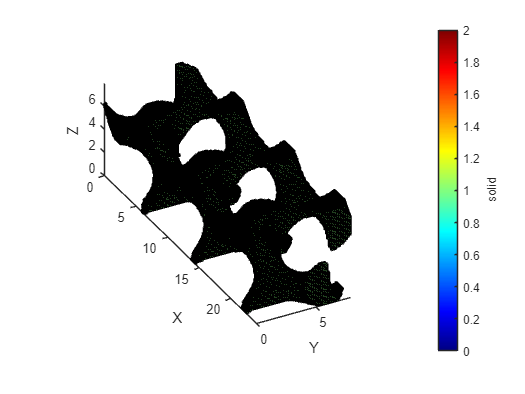

axesVoxel = myCell.plot("voxel","solid");

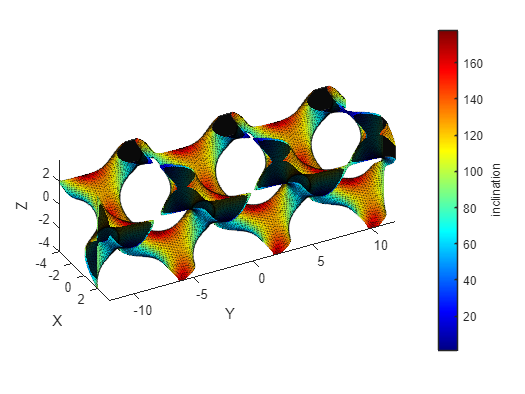

axesVoxel = myCell.plot("SurfMesh","inclination");

**TEST SECTION - 2**

**Y-DIRECTION**

**PLOT REFERENCE CASE - AbouAli2019 - Gyroid - Polymeric material - Cell size 8 mm**


N_xcells = 3; % number of cells along x-direction 

x_A = -4*N_xcells; % (mm)
x_B = 4*N_xcells; % (mm)
y_A = 1.89; % (MPa)
y_B = 42.8; % (MPa)

alpha = (y_B - y_A)/(x_B - x_A); % result 1.7046
beta = (y_A*x_B - y_B*x_A)/(x_B - x_A); % result 22.345

**STIFFNESS LINEAR GRADING OPTIMIZATION - OPTIMAL ISOVALUE c(x)**

isovalue_opt_a1 = 1/(linear_fit(1)/100); % result -2.8451
isovalue_opt_a2 = -(linear_fit(2)/100)/(linear_fit(1)/100); % result 1.4811

%test
isovalue_opt_funct = @(y) -2.8451*((1.7046*y+22.345)/1257).^(1/2.36)+1.4811; %test

x_array_test = [x_A:0.1:x_B];
isovalue_opt_array_test = isovalue_opt_funct(x_array_test);
reldens_opt_array_test = linear_fit(1)/100*isovalue_opt_array_test + linear_fit(2)/100;
YoungMod_opt_array_test = K_YoungMod_AbouAli2019*reldens_opt_array_test.^N_YoungMod_AbouAli2019;

%%%%%%%%%%%%%%%% CHECK START
figure
plot(x_array_test(:), YoungMod_opt_array_test,'-k','LineWidth',0.5);

ax = gca; ax.FontSize = 16; 

xlabel('Coordinate $x$ (mm)','interpreter','latex','fontsize',16);
ylabel('Young''s modulus $E$ (Mpa)','interpreter','latex','fontsize',16);
xlim([-13 13])
% ylim([0 7])

grid on
box on

%%%%%%%%%%%%%%%% CHECK END

isovalue_opt = '-2.8451*((1.7046*sqrt(y.*y)+22.345)/1257).^(1/2.36)+1.4811';

**STIFFNESS LINEAR GRADING OPTIMIZATION - SINGLE DIRECTION**

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID
myEQUATION = [func2str(EQ0) isovalue_opt];

% test = str2func(myEQUATION);

TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.0; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 8; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [1 3 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-2.8451*((1.7046*sqrt(y.*y)+22.345)/1257).^(1/2.36)+1.4811'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-2.8451*((1.7046*sqrt(y.*y)+22.345)/1257).^(1/2.36)+1.4811
           v1: 0
           v2: 0
    voxelSize: 0.1500
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]


calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

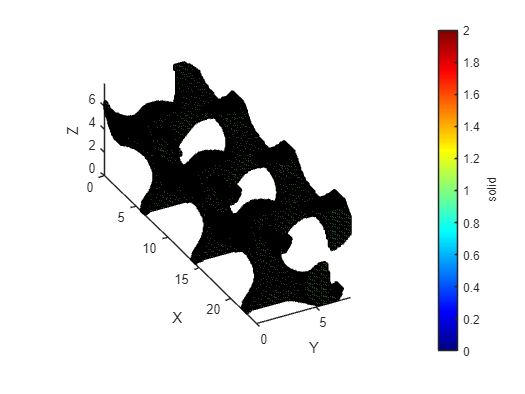

axesVoxel = myCell.plot("voxel","solid");

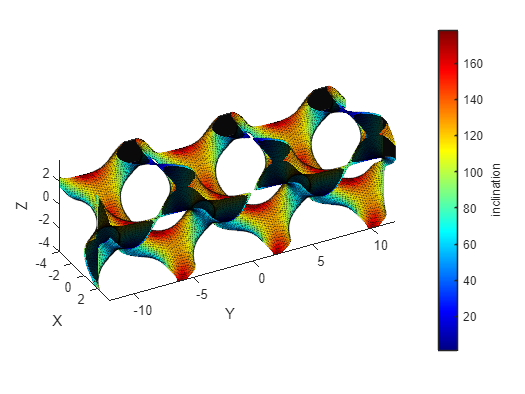

axesVoxel = myCell.plot("SurfMesh","inclination");

**RESULT OF TEST SECTIONS 1 - Y-DIRECTION**

the string "isovalue_opt = '-2.8451*((1.7046*y+22.345)/1257).^(1/2.36)+1.4811'; "

with *y has been correctly valuated

**RESULT OF TEST SECTION 2 - Y-DIRECTION **

the string "isovalue_opt = '-2.8451*((1.7046*sqrt(y.*y)+22.345)/1257).^(1/2.36)+1.4811'; "

with sqrt(y.*y) has been correctly valuated

**TEST SECTION - TRY TO IMPLENT x and y DIRECTIONS**

**2026-02-05**

**STIFFNESS LINEAR GRADING OPTIMIZATION - 2 DIRECTIONS (x,y) - TARGET DESIGN - 3x3x1 unit cells**

**Ec(r) = alpha*r + beta**

N_xcells = 3; % number of cells along x-direction 
N_ycells = 3; % number of cells along y-direction 

r_A = 0; % (mm)
r_B = CELLSIZE/2*N_xcells; % (mm)
y_A = 42.8; % (MPa)
y_B = 1.89; % (MPa)

alpha = (y_B - y_A)/(r_B - r_A); % result -3.4092        1.7046
beta = (y_A*r_B - y_B*r_A)/(r_B - r_A); % result 42.8    22.345

**STIFFNESS LINEAR GRADING OPTIMIZATION - OPTIMAL ISOVALUE c(x)**

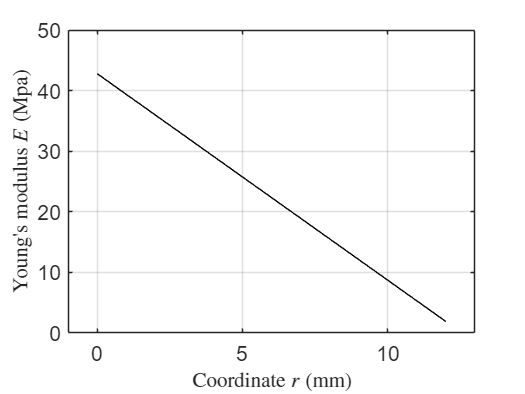

isovalue_opt_a1 = 1/(linear_fit(1)/100); % result -2.8451
isovalue_opt_a2 = -(linear_fit(2)/100)/(linear_fit(1)/100); % result 1.4811

%test
isovalue_opt_funct = @(r) -2.8451*((-3.4092*r+42.8)/1257).^(1/2.36)+1.4811; %test

r_array_test = [r_A:0.1:r_B];
isovalue_opt_array_test = isovalue_opt_funct(r_array_test);
reldens_opt_array_test = linear_fit(1)/100*isovalue_opt_array_test + linear_fit(2)/100;
YoungMod_opt_array_test = K_YoungMod_AbouAli2019*reldens_opt_array_test.^N_YoungMod_AbouAli2019;

%%%%%%%%%%%%%%%% CHECK START
figure
plot(r_array_test(:), YoungMod_opt_array_test,'-k','LineWidth',0.5);

ax = gca; ax.FontSize = 16; 

xlabel('Coordinate $r$ (mm)','interpreter','latex','fontsize',16);
ylabel('Young''s modulus $E$ (Mpa)','interpreter','latex','fontsize',16);
xlim([-1 13])
% ylim([0 7])

grid on
box on

%%%%%%%%%%%%%%%% CHECK END

isovalue_opt = '-2.8451*((-3.4092*sqrt(x.^2+y.^2)+42.8)/1257).^(1/2.36)+1.4811';

**STIFFNESS LINEAR GRADING OPTIMIZATION - SINGLE DIRECTION**

EQ0 = @(x,y,z) sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x); %GYROID
myEQUATION = [func2str(EQ0) isovalue_opt];

% test = str2func(myEQUATION);

TYPE = "single"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; % Standard Definition of Unit Cell Type

V1 = 0.0; % Geometry Parameter 1
V2 = 0.0; % Geometry Parameter 2
VOXSIZE = 0.15; % Voxelsize - (size of voxel grid used for analysis)
CELLSIZE = 8; % Unit cell size in mm
VOLUMESHAPE = 'box'; % Shape of the unit cell
ROTATION = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
PHASESHIFT = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm

% Define the bulkSize using the bulkSize object
N = [N_xcells N_ycells 1]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize(VOLUMESHAPE,CELLSIZE.*N); % Box centered at origin with [lx,ly,lz]

% Use inputs to create the transform object
if isMATLABReleaseOlderThan('R2022b') % Compatability for older versions of matlab
    TFORM = affine3d([CELLSIZE 0 0 PHASESHIFT(1); 0 CELLSIZE 0 PHASESHIFT(2); 0 0 CELLSIZE PHASESHIFT(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(CELLSIZE,ROTATION,PHASESHIFT); % Other types of transforms can be defined - this example uses a similarity transform
end

% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME)
myCell = UnitCell(TYPE,myEQUATION,V1,V2,VOXSIZE,TFORM,VOLUME)

myCell =   UnitCell with properties:

         type: "single"
     equation: '@(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-2.8451*((-3.4092*sqrt(x.^2+y.^2)+42.8)/1257).^(1/2.36)+1.4811'
            u: @(x,y,z)sin(2*pi*x).*cos(2*pi*y)+sin(2*pi*y).*cos(2*pi*z)+sin(2*pi*z).*cos(2*pi*x)-2.8451*((-3.4092*sqrt(x.^2+y.^2)+42.8)/1257).^(1/2.36)+1.4811
           v1: 0
           v2: 0
    voxelSize: 0.1500
        tform: [1×1 simtform3d]
           FV: []
            F: []
            M: [1×1 metrics]
            B: [1×1 bulkSize]


calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 0;  % 1 or 0 to turn on or off.
calcSurfMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfMesh); % Do the thing!

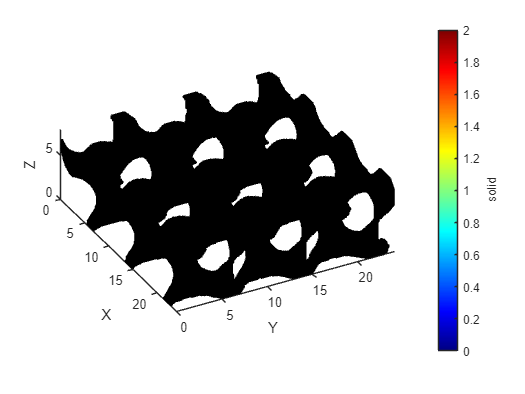

axesVoxel = myCell.plot("voxel","solid");

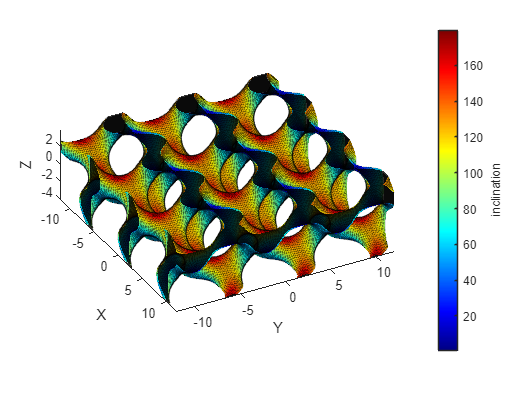

axesVoxel = myCell.plot("SurfMesh","inclination");